# Example Script to try things

Load some data

Add the US Census data for 1900 to 2000.

years = (1900:10:2000);                                  % Time interval
pop = [75.995 91.972 105.711 123.203 131.669 ...         % Population Data
   150.697 179.323 213.212 228.505 250.633 265.422]

pop =    75.9950   91.9720  105.7110  123.2030  131.6690  150.6970  179.3230  213.2120  228.5050  250.6330  265.4220


Plot the population data against the year.

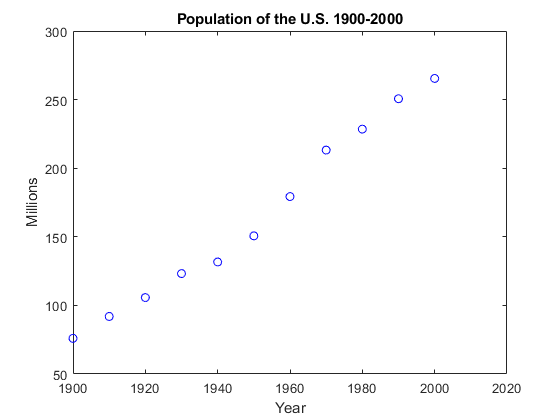

plot(years,pop,'bo');                                    % Plot the population data
axis([1900 2020 0 400]);
title('Population of the U.S. 1900-2000');
ylabel('Millions');
xlabel('Year')
ylim([50 300])

## Testing live tasks

Add some missing data

pop([5,7,8]) = NaN;

Try cleaning with a live task

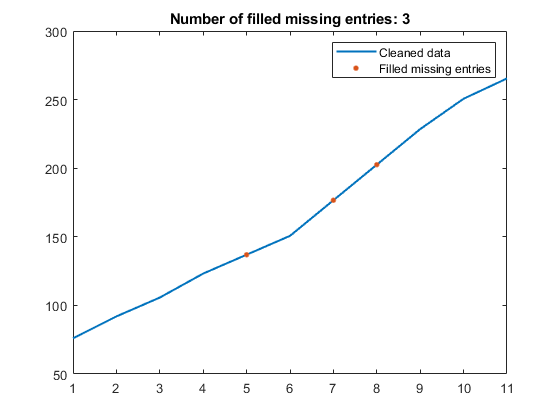

% Fill missing data
[cleanedData,missingIndices] = fillmissing(pop,'linear');

% Visualize results
clf
plot(cleanedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')
hold on

% Plot filled missing entries
plot(find(missingIndices),cleanedData(missingIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])

hold off
legend

clear missingIndices